# Демодуляция. Часть 2.

# Double Sideband Transmitted Carrier 

# (AM-DSB-TC)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Когерентная демодуляция с помощью PLL

Для качественного приема АМ-сигналов когерентным способом необходимо точное совпадение частоты и фазы несущей и генератора в приемнике. Чтобы этого добиться, нужно использовать систему фазовой автоподстройки частоты (phase-locked loop - PLL). В этом случае схема приемного устройства будет иметь вид:

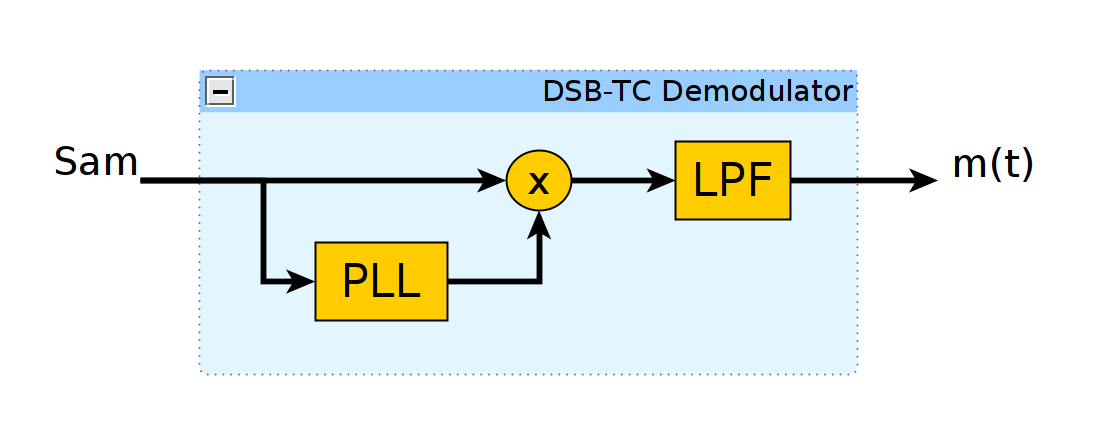

Классическая PLL состоит из трех основных блоков: фазового детектора (phase detector - PD), петлевого фильтра (loop filter - LF) и генератора, управляемого напряжением (numericaly controled oscillator - NCO). Фазовый детектор вычисляет разность фаз между несущей и NCO. Схема PLL представлена ниже:

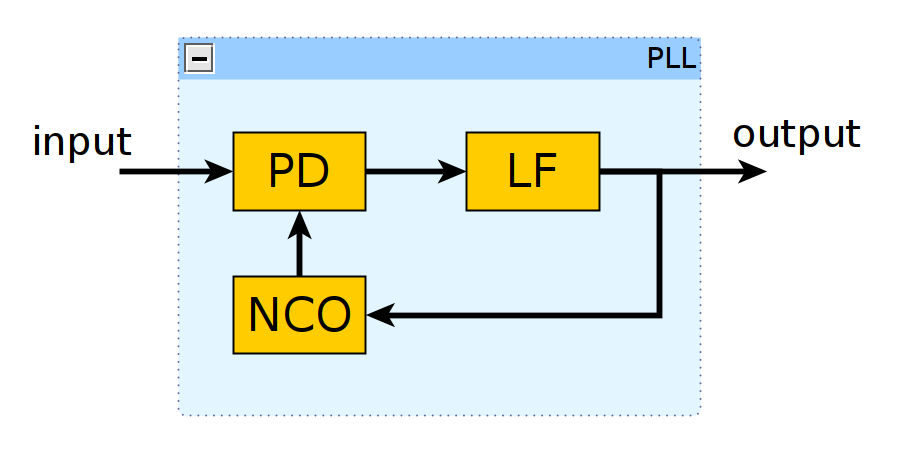

Фазовый детектор можно реализовать с помощью обычного умножителя. Будем считать, что несущую можно представить в виде:

$u_c =A\cdot \sin \left(\omega_с t+\phi_0 \right)=A\cdot \sin \left(\Phi_с \left(t\right)\right)$.

Также пусть мгновенная фаза несущей в момент времени $t_0$ равна $\Phi_с \left(t_0 \right)$ рад., а фаза NCO - $\Phi_{\textrm{NCO}} \left(t_0 \right)=\Phi_с \left(t_0 \right)+\Delta$рад. Тогда получаем:

 $A\cdot \sin \left(\Phi_с \left(t_0 \right)\right)\cdot \cos \left(\Phi_{\textrm{NCO}} \left(t_0 \right)\right)=A\cdot \sin \left(\Phi_с \left(t_0 \right)\right)\cdot \cos \left(\Phi_с \left(t_0 \right)-\Delta \right)=A\cdot 0\ldotp 5\cdot \sin \left(\Delta \right)+A\cdot 0\ldotp 5\cdot \sin \left(2\Phi_c \left(t_0 \right)-\Delta \right)$.

Слагаемое с удвоенной частотой можно убрать с помощью низкочастотного фильтра. Если этого не сделать, то оно в любом случае в дальнейшем будет удалено с помощью петлевого фильтра. Поэтому данным слагаемым можно пренебречь. То есть, отклик фазового детектора можно считать равным $A\cdot 0\ldotp 5\cdot \sin \left(\Delta \right)$. В случае, когда PLL находится в режиме синхронизации, расстройка по фазе будет близка к нулю, а значит $\sin \left(\Delta \right)\simeq \Delta \ldotp$ Таким образом, сигнал на выходе детектора будет приближенно равен $A\cdot 0\ldotp 5\cdot \Delta$. Величину $k_d =A\cdot 0\ldotp 5$ называют коэффициентом усиления детектора. Обратите внимание, что она зависит от амплитуды несущей.

Сигнал с выхода фазового детектора передается на вход петлевого фильтра, который удаляет шумы, присутствующий в сигнале, а также задает динамические характеристики PLL. Обычно фильтр реализуется в виде пропорциональной и интегрирующей ветвей, коэффициенты усиления которых равны $k_p$ и $k_i$ соответственно. Схема фильтра представлена ниже:

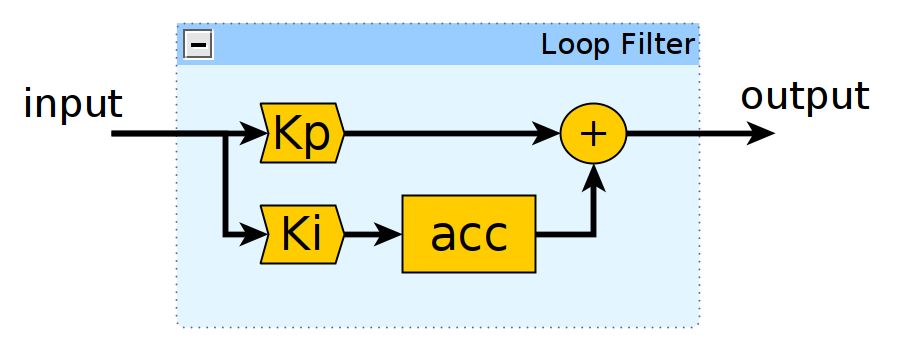

Эти коэффициенты рассчитываются на основе других характеристик PLL, а именно коэффициента демпфирования и шумовой полосы. Коэффициент демпфирования определяет степень осциляций при вхождении PLL в режим синхронизации. Шумовая полоса характеризует, как сильно будет ослаблятся шум на выходе PLL. Чем меньше полоса - тем меньше шума. Однако, уменьшение шумовой полосы приводит к существенному увеличению времени вхождения в режим синхронизации и уменьшает полосу захвата PLL. Формулы для расчета коэффициентов фильтра представлены ниже:

$k_p =\frac{4\cdot \zeta \cdot B_n }{k_d \cdot \left(\zeta +\frac{1}{4\cdot \zeta }\right)},$    $k_i =\frac{4\cdot {B_n }^2 }{k_d \cdot {\left(\zeta +\frac{1}{4\cdot \zeta }\right)}^2 }$,

 где $\zeta$ - коэффициент демпфирования, $B_n$ = $B\cdot f_s$ - нормированная шумовая полоса, $B$- шумовая полоса в герцах, $f_s$ - частота дискретизации в герцах.

Сигнал с выхода петлевого фильтра изменяется частоту управляемого генератор и тем самым подстраивает его фазу для уменьшения ошибки $\Delta$. Значание фазы NCO в аналитическом виде можно записать так:

 
$$\Phi_{\textrm{NCO}} \left(t\right)=\int_{-\infty }^t \left(\omega_0 +u_f \left(\tau \right)\right)d\tau ,$$


где $\omega_0$ - частота NCO при отсутствии входнго воздействия, $u_f \left(t\right)$ - сигнал на выходе петлевого фильтра. Таким образом, управляемый генератор по сути представляет из себя интегратор.

Так как в случаем DSB-TC модуляции несущая в сигнале присутствует в явном виде, для ее восстановления можно принятый сигнал непосредственно подавать на вход PLL. 

Для реализации всех рассмотренных выше преобразований был создан Matlab System Object, описание которого находится в файле AmSignalPLL.m. Ниже представлен скрипт, выполняющий когерентный прием сигнала с амплитудной модуляцией. С помощью переменной FreqOffset можно изменять расстройку между частотой несущей и начальной частотой управляемого генератора.

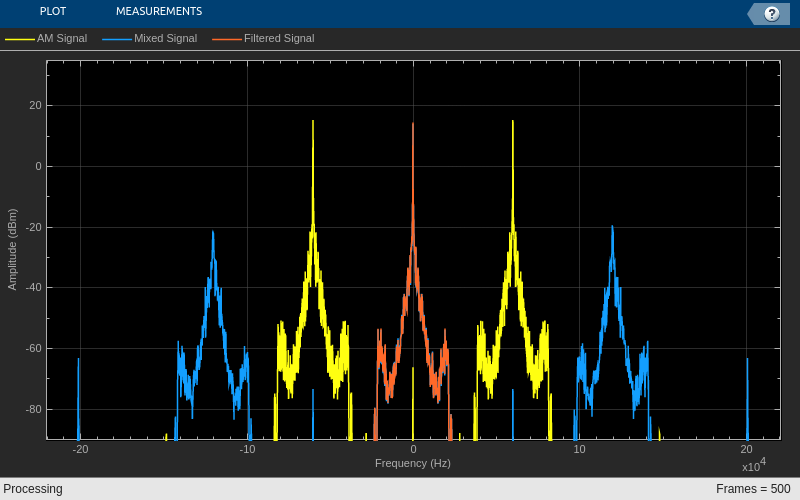

clc; clear; close all;
addpath('matlab/DSB_TC');

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 3;             % коэффициент усиления аудиосигналарассмотрим
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

% расстройка по частоте (Hz)
FreqOffset = 1000;

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_TC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% фапч для восстановления несущей
% параметры фапч зависят от амплитуды входного сигнала
% его амплитуда меняется поэтому берем среднее значение, равное 0.27
AmPLL = AmSignalPLL( ...
    'SampleFrequency', SignalFs, ...
    'NoiseBandwidth', 100, ...
    'Dampingfactor', 0.7, ...
    'CentralFrequency', Fc + FreqOffset, ...
    'SignalAmp', 0.27 ...
    );

% рассчет коэффициентов фильтра нижних частот
H = Audio_Lowpass_FIR_Coeff();

% создание объекта для фильтрации
LowpassFIR = dsp.FIRFilter(H.Numerator);

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Mixed Signal', 'Filtered Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и выделение синфазного канала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1);

    % восстанавливаем несущую
    [Carrier, Offset] = AmPLL(AmSignal);

    % смешивание АМ-сигнала и несущей
    MixedSignal = AmSignal .* Carrier;

    % фильтрация сигнала
    BasebandSignal = LowpassFIR(MixedSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(BasebandSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal MixedSignal BasebandSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены преобразования в частотной области. Желтым обозначен спектр принимаемого АМ-сигнала. Синим - спектр на выходе смесителя. Можно увидеть, что он состоит из информационного сообщения и сигнала на удвоенной частоте несущей. После фильтрации остается только информационное сообщение (красный).

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно оценить, что при расстройке в 100 Гц демодулированный сигнал не содержит искажений. При расстройке в 1000 Гц сначала слышен сильный свист, а потом качество сигнала исправляется. Этот временный свист соответствует периоду вхождения PLL в режим синхронизации. Из-за большей расстройки по частоте длительность этого процесса увеличивается. При расстройке в 5000 Гц, слышны сильные искажения. Это происходит из-за того, что расстройка по частоте превышает полосу захвата PLL, поэтому PLL не может войти в режим синхронизации.

В файле *DSB_TC_Receiver_Part_2_1.slx* представлена Simulink модель когерентного демодулятора, который ранее был реализован ввиде скрипта. 

 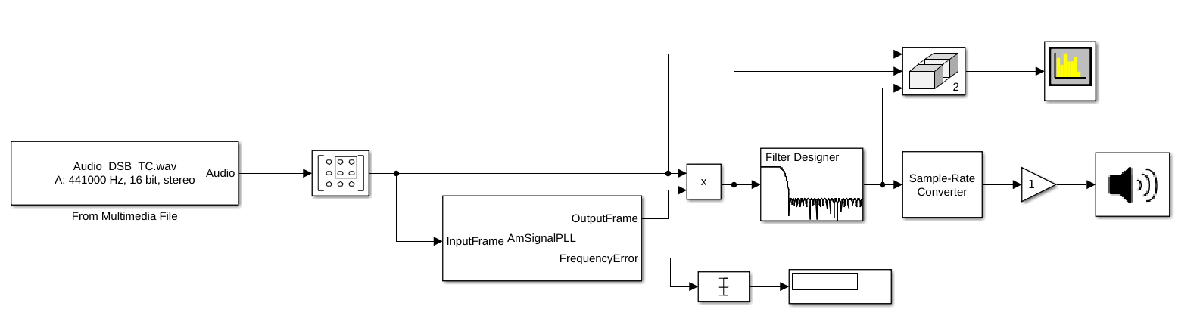

### 2. Когерентная демодуляция при квадратурном приеме

Рассмотрим как изменится структура когерентного демодулятора в случае квадратурного приема. Сигнал теперь комплексный с односторонним спектром. Для восстановления несущей также необходимо использовать PLL. Отличае от случая действительнго сигнала заключается в устройстве фазового детектора. При квадратурном приеме несущую можно представить в виде комплексной экспоненты ${A\cdot e}^{j\cdot \Phi_с \left(t\right)}$. Выходной сигнал NCO также будет комплексным - $e^{-j\cdot \Phi_{\textrm{NCO}} \left(t\right)}$. Как и ранее через $\Phi_с \left(t\right)$ и $\Phi_{\textrm{NCO}} \left(t\right)=\Phi_с \left(t\right)-\Delta$ обозначены мгновенные фазы несущей и NCO. Фазовый детектор представляет из себя умножитель, после которого располается блок вычисления аргумента комплексного числа. Это можно записать в аналитическом виде:


$${s_{\textrm{mix}} =A\cdot e}^{j\cdot \Phi_с \left(t\right)} \cdot e^{-j\cdot \Phi_{\textrm{NCO}} \left(t\right)} ={A\cdot e}^{j\cdot \left\lbrack \Phi_с \left(t\right)-\Phi_с \left(t\right)+\Delta \right\rbrack } ={A\cdot e}^{j\cdot \Delta } ,$$



$$s_d =\arg \left\lbrace s_{\textrm{mix}} \right\rbrace =\arg \left\lbrace {A\cdot e}^{j\cdot \Delta } \right\rbrace =\Delta ,$$


где $s_{\textrm{mix}}$ - сигнал на выходе умножителя, а $s_d$- сигнал на выход фазового детектора.

Можно увидеть, что в случае квадратурного приема сигнал на выходе фазового детектора не зависит от амплитуды несущей, а коэффициент усиления детектора $k_d$ равен единице. Остальная часть PLL полностью совпадает с реализацией для действительного принимаемого сигнала.

Для реализации всех описанных выше преобразований был создан Matlab System Object, описание которого находится в файле AmComplexPLL.m. Ниже представлен скрипт, выполняющий когерентный прием сигнала с амплитудной модуляцией. С помощью переменной FreqOffset можно изменять расстройку между частотой несущей и начальной частотой управляемого генератора.

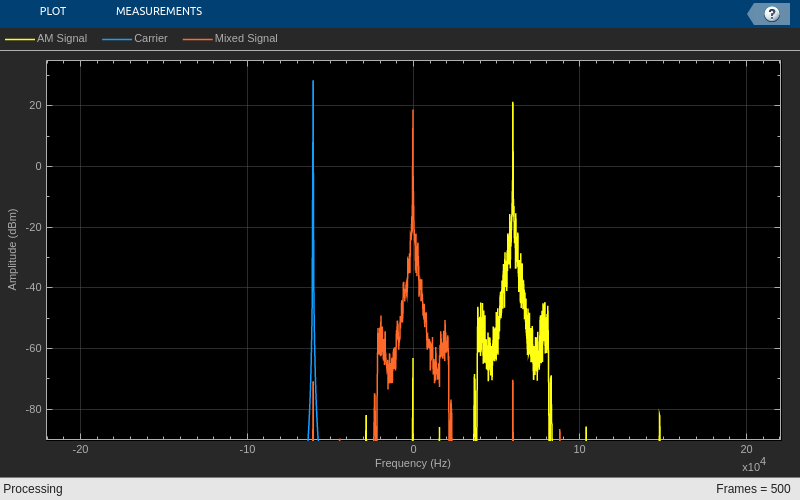


clc; clear; close all;
addpath('matlab/DSB_TC');

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 1;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации
Fc = 60e3;                % частота несущей

% расстройка по частоте (Hz)
FreqOffset = 1000;

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_TC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% фапч для восстановления несущей
AmPLL = AmComplexPLL( ...
    'SampleFrequency', SignalFs, ...
    'NoiseBandwidth', 100, ...
    'Dampingfactor', 0.7, ...
    'CentralFrequency', Fc + FreqOffset ...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Carrier', 'Mixed Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и формирование комплексного сигнала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1) + 1j*AmSignal(:,2);

    % восстанавливаем несущую
    [Carrier, Offset] = AmPLL(AmSignal);

    % смешивание АМ-сигнала и несущей
    MixedSignal = AmSignal .* conj(Carrier);
    MixedSignal = real(MixedSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp*DownSampler(MixedSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([AmSignal conj(Carrier) MixedSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены преобразования в частотной области. Желтым обозначен спектр принимаемого АМ-сигнала. Так как прием квадратурный, спектр сигнала комплексный и расположен только в положительной области частот. Синим цветом представлен сигнал на выходе NCO PLL, а красным - сигнал на выходе смесителя. 

% проигрывание полученного сообщения
sound(Message, AudioFs);

При прослушавании принятого сигнала при разных значениях расстройки по частоте получаем те же самые искажения, что и для действительного случая. При расстройке по частоте в 5000 Гц сигнал на выходе NCO содержит множество гармоник и не является комплексной экспонентой. Это означает, что PLL не находится в режиме синхронизации.

В файле *DSB_TC_Receiver_Part_2_2.slx* представлена Simulink модель когерентного демодулятора в квадратурном случае. 

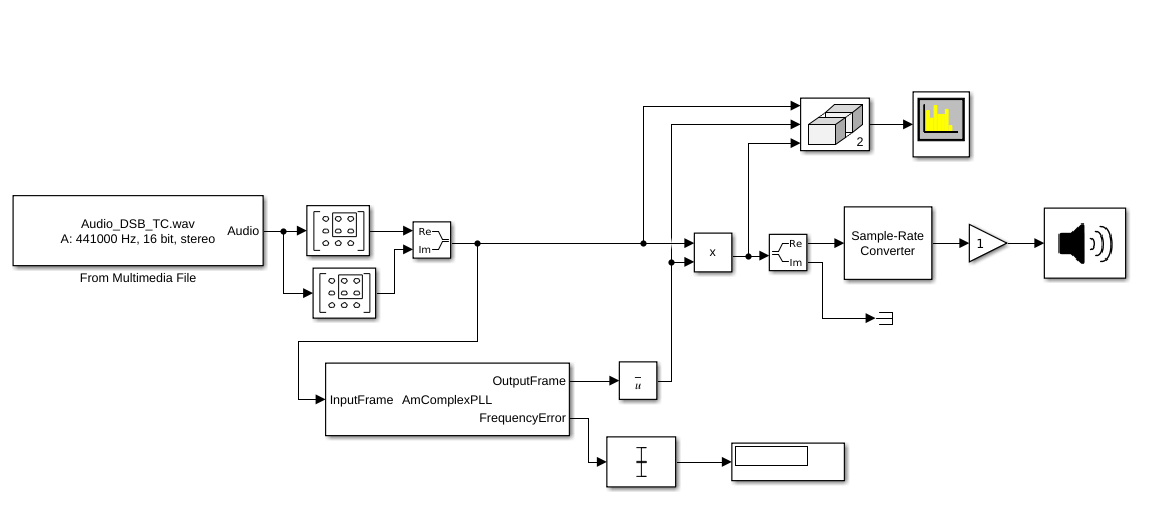

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR

- F. Gardner Phaselock Techniques

- M. Rice Digital Communications. A Discrete Time Approach